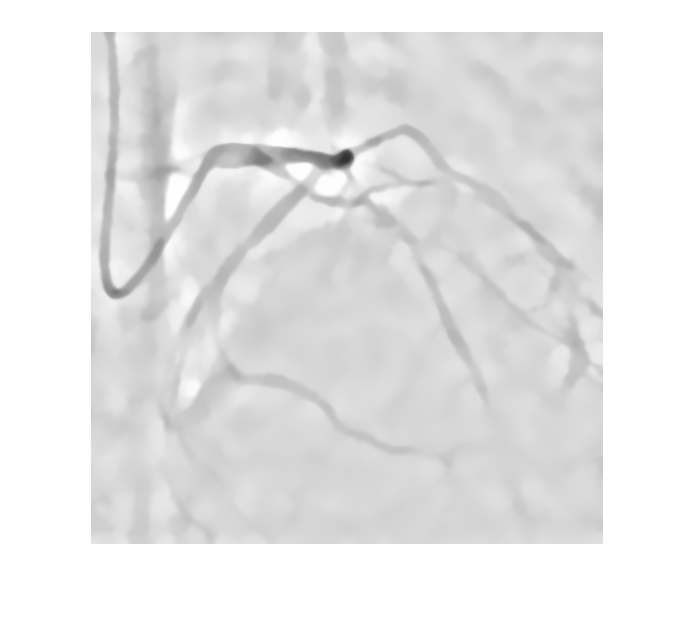

clear all 
close all
A=imread('rankfiltered.jpg');
noisyLAB = rgb2lab(A);
roi = [210,24,52,41];
patch = imcrop(noisyLAB,roi);
patchSq = patch.^2;
edist = sqrt(sum(patchSq,3));
patchSigma = sqrt(var(edist(:)));
DoS = 1.1*patchSigma;
denoisedLAB = imnlmfilt(noisyLAB,'DegreeOfSmoothing',DoS);
denoisedRGB = lab2rgb(denoisedLAB,'Out','uint8');
imshow(denoisedRGB)

Test_Image=denoisedRGB;
% A=rgb2gray(d);
% A=ordfilt2(d,5,ones(7,7));
Test_Image=gray2d(Test_Image);
% %i=rgb2gray(j);
% AInv = imcomplement(A);
% 
% BInv = imreducehaze(AInv);
% B = imcomplement(BInv);
% BInv = imreducehaze(AInv, 'Method','approx','ContrastEnhancement','boost');
% BImp = imcomplement(BInv);
% figure, montage({A BImp});


Test_Image=gray2d(d,BImp);

% Test_Image =d;

Resized_Image = imresize(Test_Image, [584 565]);
Converted_Image = im2double(Test_Image);
% Lab_Image=Converted_Image;
Lab_Image = rgb2lab(Resized_Image);
% figure,imshow(Lab_Image);

fill = cat(3, 1,0,0);
Filled_Image = bsxfun(@times, fill, Lab_Image);
Reshaped_Lab_Image = reshape(Filled_Image, [], 3);
[C, S] = pca(Reshaped_Lab_Image);
S = reshape(S, size(Lab_Image));
S = S(:, :, 1);

Gray_Image = (S-min(S(:)))./(max(S(:))-min(S(:)));

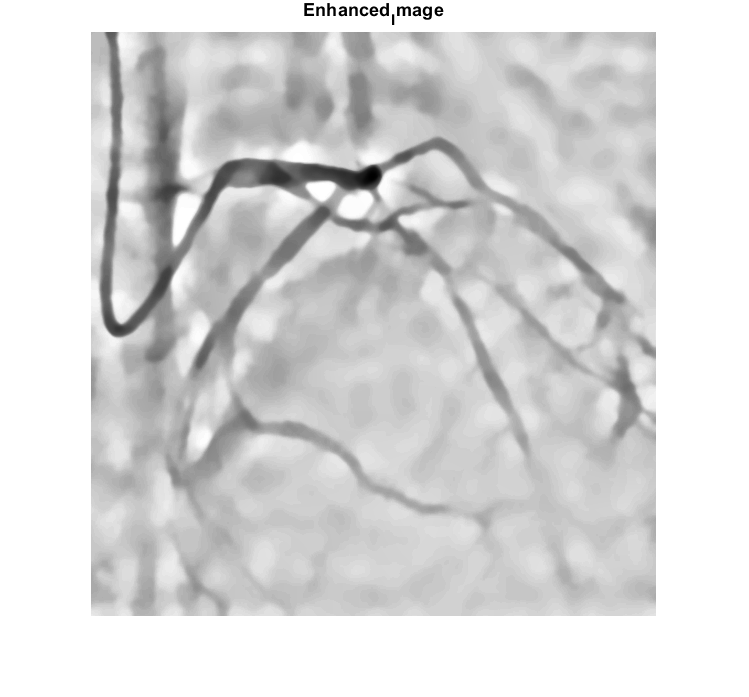

Enhanced_Image = adapthisteq(Gray_Image, 'numTiles', [8 8], 'nBins', 128);

figure, imshow(Enhanced_Image)
title('Enhanced_Image')

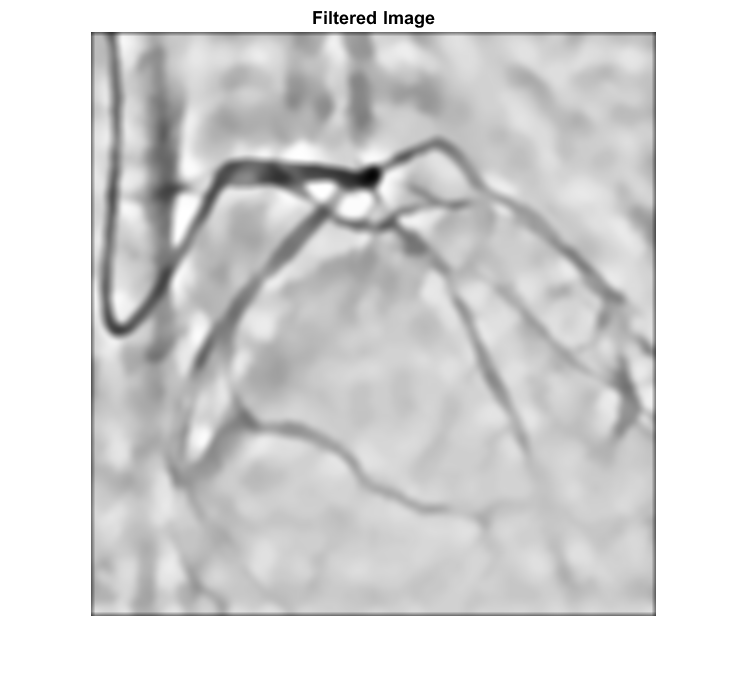

Avg_Filter = fspecial('average', [9 9]);
Filtered_Image = imfilter(Enhanced_Image, Avg_Filter);
figure, imshow(Filtered_Image)
title('Filtered Image')

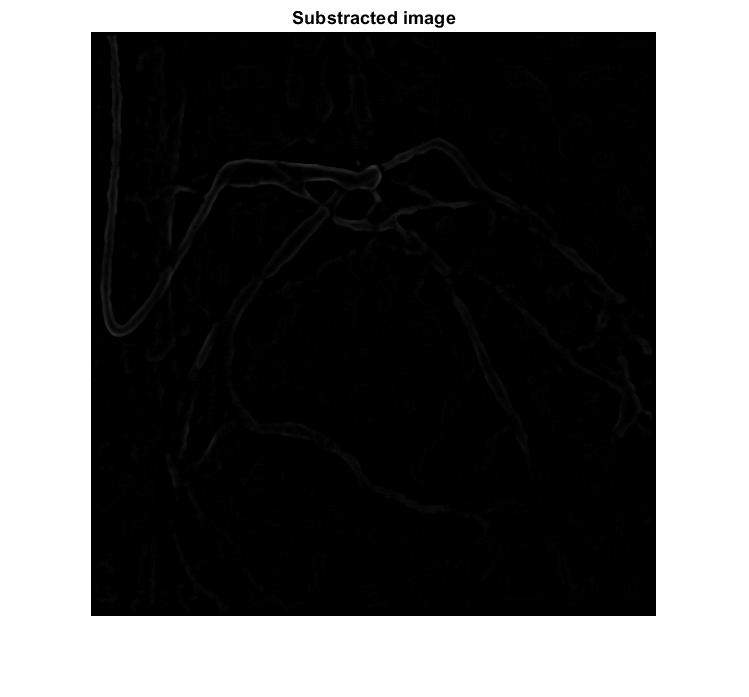

Substracted_Image = imsubtract(Filtered_Image,Enhanced_Image);
figure, imshow(Substracted_Image)
title('Substracted image')

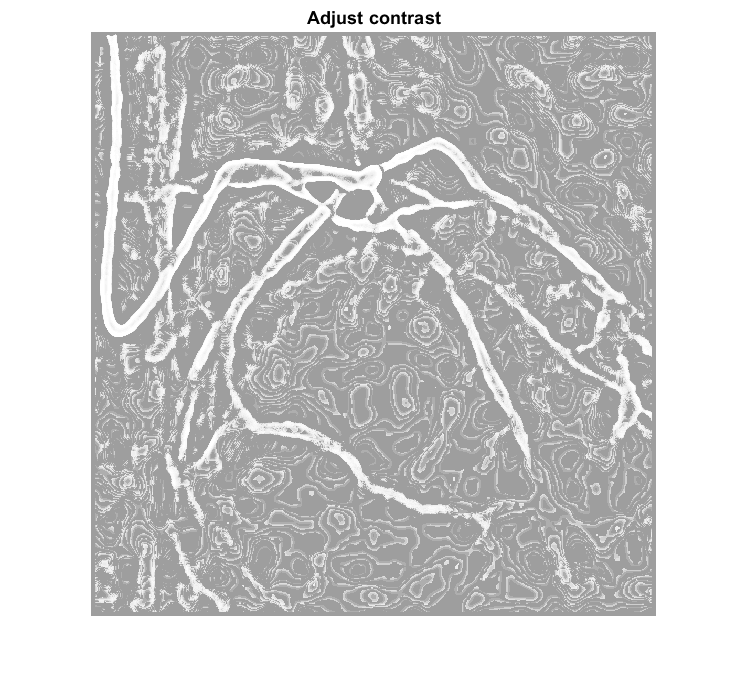


A=histeq(Substracted_Image);        %adjust contrast
figure, imshow(A)
title('Adjust contrast')

level = 0.02452%Threshold_Level(Substracted_Image);

level = 0.0245

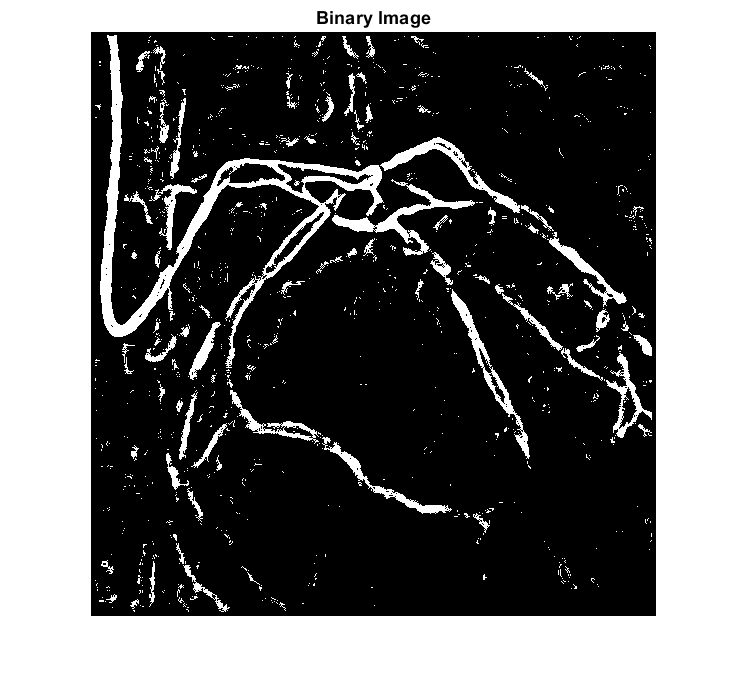

Binary_Image = im2bw(Substracted_Image, level-0.008);
figure, imshow(Binary_Image)
title('Binary Image')

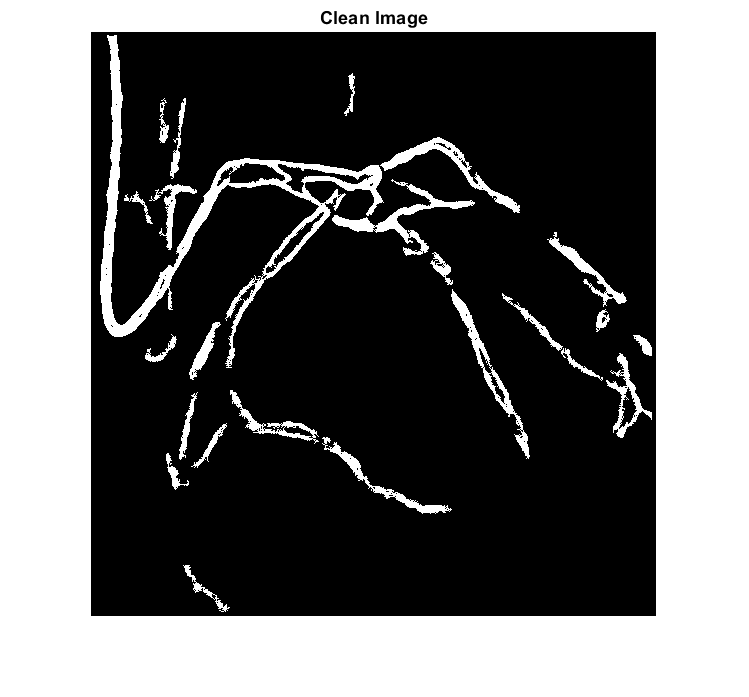

Clean_Image = bwareaopen(Binary_Image, 150);
figure, imshow(Clean_Image)
title('Clean Image')

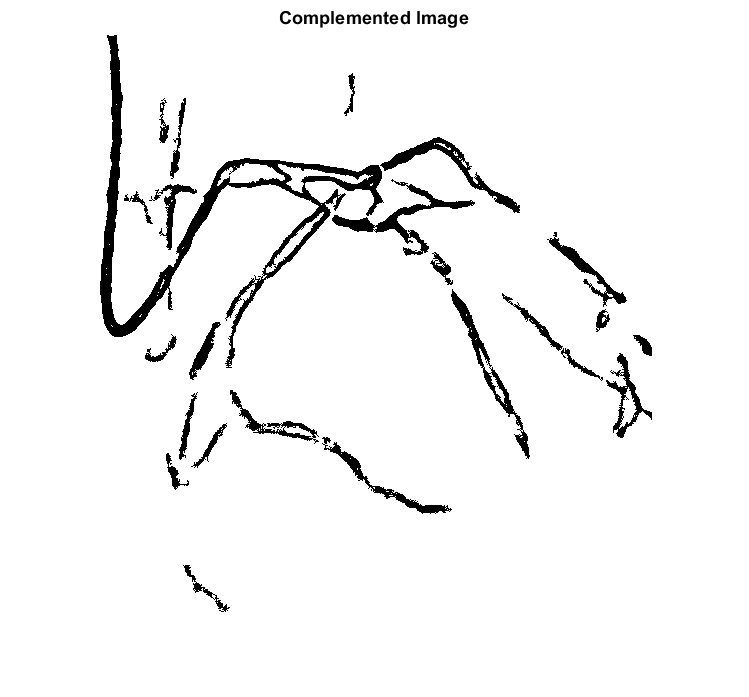

Complemented_Image = imcomplement(Clean_Image);
figure, imshow(Complemented_Image)
title('Complemented Image')

gray=bi2gray(Complemented_Image);

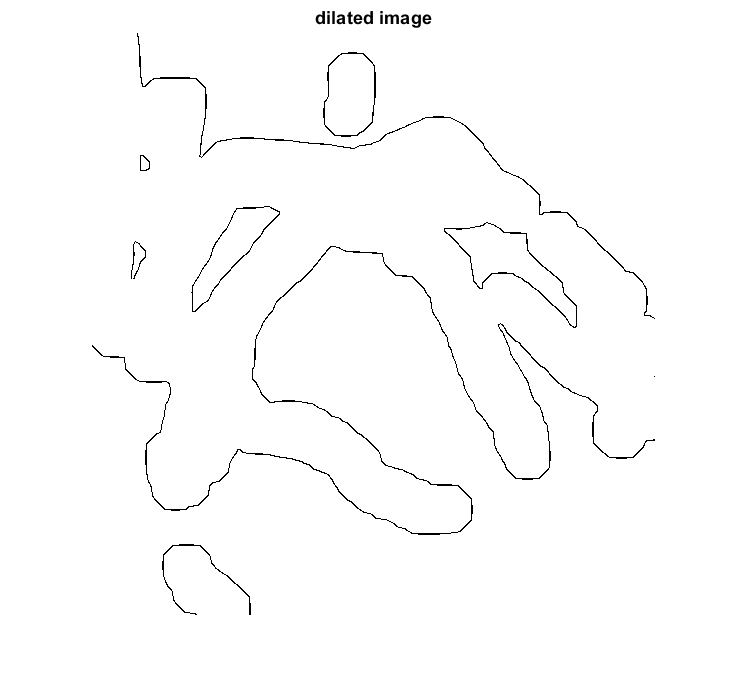

SE=strel("disk",21);
dil=imdilate(Clean_Image,SE);


dil=edge(dil,"canny");
dil=imcomplement(dil);
figure, imshow(dil)
title('dilated image')


Complemented_Image=im21d(Complemented_Image);
dil=im21d(dil);

fpts=bpt(Complemented_Image)

fpts =         1712        1713        1719        1720        1721        2277        2278        2279        2280        2281        2282        2283        2284        2285        2286        2842        2843        2844        2845        2846        2847        2848        2849        2850        2851        3408        3409        3410        3411        3412        3413        3414        3415        3416        3973        3974        3975        3976        3977        3978        3979        3980        3981        4538        4539        4540        4541        4542        4543        4544


bpts=bpt(dil)

bpts =          612        1177        1742        2307        2308        2873        3438        4003        4568        5133        5698        6263        6828        6829        7394        7959        8524        9089        9654       10219       10784       11349       11558       11559       11560       11561       11562       11563       11564       11565       11566       11914       12116       12117       12118       12119       12120       12121       12122       12123       12124       12125       12126       12127       12128       12129       12130       12131       12132       12133


[r c]=size(fpts);
rf=randi(c,10,1)

rf =        14367
         783
       18604
       20463
       14871
       16602
       16282
        8594
       14361
        3751


[r c]=size(bpts);
rb=randi(c,10,1)

rb =         3482
         157
        1366
         228
         479
        4061
        3427
        1564
        4686
         170



nfpts=fpts(rf)

nfpts =       157653       40710      213993      239086      162197      180714      176987      105734      157647       78789


nbpts=bpts(rb)

nbpts =       220853       24015      111108       26076       48371      248266      216898      120388      289946       25495



[BW,maskedImage] = segmentvessal(gray,nfpts,nbpts)

BW = 584×565 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

maskedImage =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

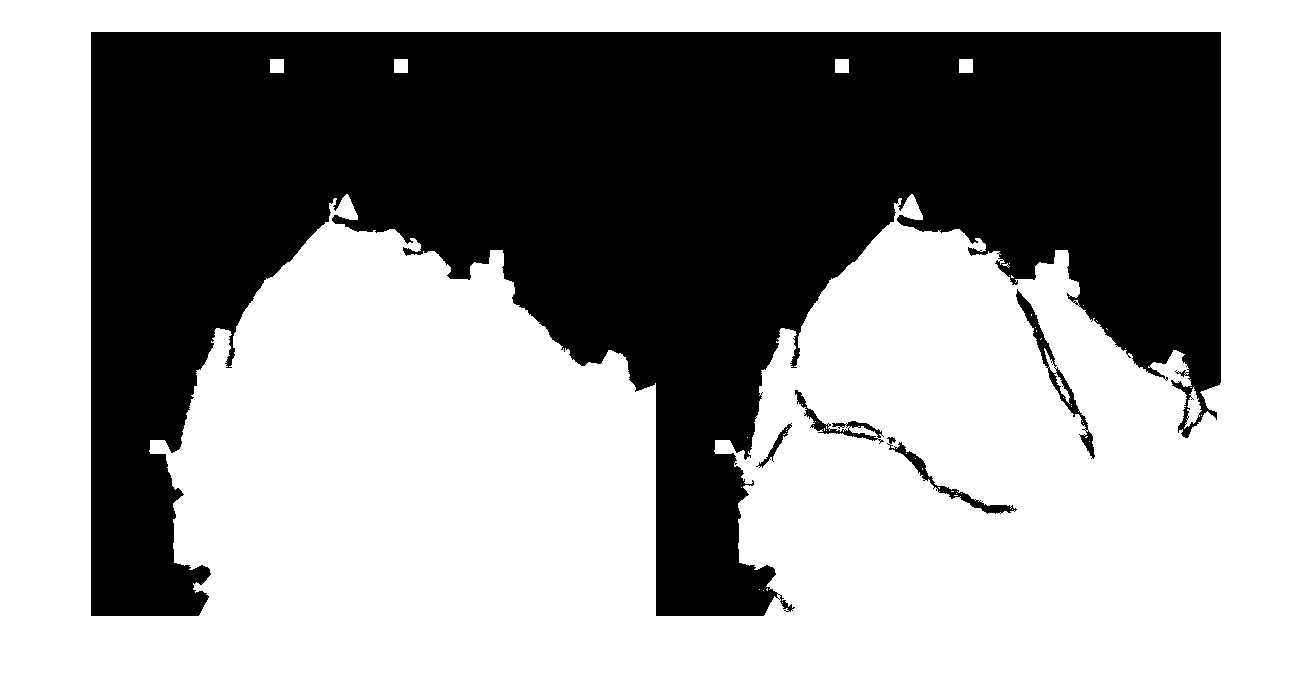


imshowpair(BW,maskedImage,'montage')

Functions

%==============================graph cut===================================

function [BW,maskedImage] = segmentvessal(X,fpt,bpt)
X = imadjust(X);

% Graph cut
foregroundInd = fpt ;
backgroundInd = bpt ;
L = superpixels(X,1750);
BW = lazysnapping(X,L,foregroundInd,backgroundInd);

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end
%================to convert gray 2d to 3 chanel(rgb) gray image=============
function [outImg]=gray2d(bw)
[r, c,l]=size(bw);
bw=imresize(bw,[r,c]);
if l==3;
    outImg=bw;
else
  for x=1:3;
    for i=1:r
       for j=1:c
           outImg(i,j,x)=bw(i,j);
       end
    end
 end
end

end

%==================to convert binary to unit8 image==========================
function [outImg]=bi2gray(bw)
[r, c]=size(bw);

outImg=ones([r c]);
for i=1:r
    for j=1:c
        if bw(i,j)==1;
            outImg(i,j)=255;
        else
            outImg(i,j)=0;
        end
    end
end
end
%=======================to convert 2d image to 1d image=======================
function [outImg]=im21d(bw)
[r, c]=size(bw);

for i=1:r
    for j=1:c
        outImg((i-1)*c +j)=bw(i,j);
    end
end
end
%===========to extrect lication of balck points  from 1d binary image==========
function [outImg]=bpt(bw)
[l c]=size(bw);
x=1;
for i=1:c
    if bw(i)==0
        outImg(x)=i;
        x=x+1;
%     else
    end
end

end

